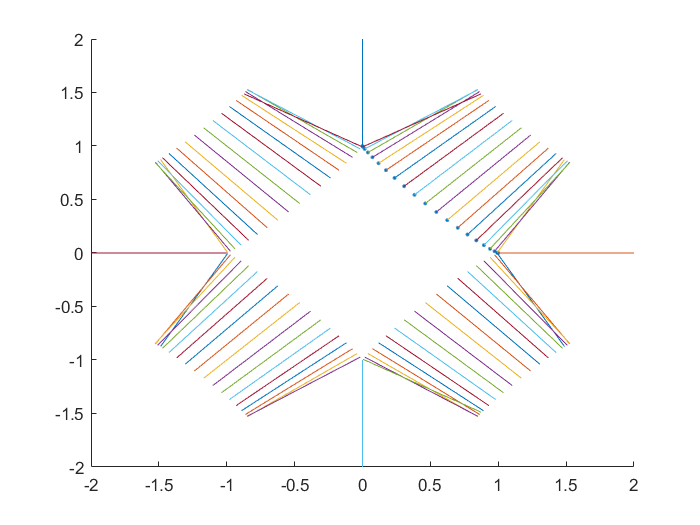

clear;
%超椭圆数据生成
count = 20;
a = 1;
b = 1;
m = 0.9;
theta = 0:(pi/2/count):pi/2;
len = length(theta);
Points = [a*cos(theta').^(2/m), b*sin(theta').^(2/m)];
scatter(Points(:,1),Points(:,2),'.');
hold on;
Gradient = [m/a*Points(:,1).^(m-1),m/b*Points(:,2).^(m-1)];
Gradient(1,:) = Points(1,:);
Gradient(21,:) = Points(21,:);
GradientLen = sqrt(Gradient(:,1).^2+Gradient(:,2).^2);

Gradient = [Gradient(:,1)./GradientLen, Gradient(:,2)./GradientLen,];
Points = [Points(:,1),Points(:,2);-Points(1:20,1),Points(1:20,2)];
Points = [Points(:,1),Points(:,2);Points(2:40,1),-Points(2:40,2)];
Gradient = [Gradient(:,1),Gradient(:,2);-Gradient(1:20,1),Gradient(1:20,2)];
Gradient = [Gradient(:,1),Gradient(:,2);Gradient(2:40,1),-Gradient(2:40,2)];

Normals = Gradient;

for i=1:4*len-4
plot([Points(i,1),Points(i,1)+Gradient(i,1)],[Points(i,2),Points(i,2)+Gradient(i,2)])
end
hold off;

n = 4*length(theta)-4;

k = 5*ones(n,1);
% k(5:9)=4*ones(5,1);
% k(11:13)=4*ones(3,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
% 计算各点支撑半径
SupportSizes = zeros(n,1);
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);


% 设置拟合系数
ApproxArgs = zeros(n,1);
maxApproxArg=1;
minApproxArg=0.3;
maxerr=max(Err);
minerr=min(Err);


%自适应地生成maxApproxArgs值
for i=1:n
        ApproxArgs(i) = maxApproxArg -(maxApproxArg - minApproxArg) ...
            *((Err(i) - minerr) / (maxerr - minerr));
%          ApproxArgs(i)=1;
end




% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        %Wendland part
        value = rbf_wend(dists(j)/SupportSizes(indices(j)));
        %shepard part
%         value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%         if(value==inf)
%             valsum=H(j);
%             rbfsum=1;
%             break;
%         end
        %Our method
%         if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
%             valsum = C(indices(j))+H(j);
%             rbfsum = 1;
%             break;
%         end
%         value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
        
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
 f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C));
% area = [-1.5,1.5,-0.7,0.7];
% fp = fimplicit(f, area);
% 
% hold on;
% scatter(Points(:,1),Points(:,2),'*');
% hold off;

% %样本点误差
% F=zeros(n,1);
% for j=1:n
%     F(j)=f(Points(j,1),Points(j,2));
% end
% e1=max(abs(F))

%测试点误差
count = 1000;
theta = 0:(pi/2/count):pi/2;
respoints = [a*cos(theta').^(2/m), b*sin(theta').^(2/m)];
for j=1:length(theta)
    F(j)=f(respoints(j,1),respoints(j,2));
end
Maxe2=max(abs(F))

Maxe2 = 0.0015

Meane2=mean(abs(F))

Meane2 = 2.6522e-04